clear all
close all

% System
R = 10; %Ohm
Rn = 1000;
L = 10e-3; %H
G_n = tf([Rn],[L,Rn+R]);
G_z = tf([L,R],[L,Rn+R]);

% sine wave with and error
fs = 10000;
f1 = 10;
f2 = 100;
t = 0:1/fs:10/f1-1/fs;
%noise
e_range = 3.3/2^12*7; % +-7 LSB TUE
e_Uin = rand(1,length(t))*2*e_range-e_range;
% R1*sin(w1t+fi1) + R2*sin(w2t+fi2) + C
fi1 = rand(1)*pi/2;
fi2 = rand(1)*pi/2;
R1 = 0.7; 
R2 = 0.3;
C = 1.65;
x = R1*sin(2*pi*f1*t+fi1)+R2*sin(2*pi*f2*t+fi2)+C;
x_err = x + e_Uin;

% System output
yN = lsim(G_n,x,t)';
yN_err = lsim(G_n,x_err,t)';
yZ = lsim(G_z,x,t)';
yZ_err = lsim(G_z,x_err,t)';

%least square method x
n = length(x);
D = [cos(2*pi*f1*t)',sin(2*pi*f1*t)',cos(2*pi*f2*t)',sin(2*pi*f2*t)', ones(n,1)]; %trig identity to cos + sin for phase
DD = D'*D;
Kx = DD\D'*x_err' % least square

Kx =     0.6991
    0.0373
    0.0208
    0.2993
    1.6500


R1x_est = sign(Kx(1))*sqrt(Kx(1)^2+Kx(2)^2)

R1x_est = 0.7001

R2x_est = sign(Kx(3))*sqrt(Kx(3)^2+Kx(4)^2)

R2x_est = 0.3000

fi1x_est = atan(-Kx(2)/Kx(1))+pi/2 

fi1x_est = 1.5175

fi2x_est = atan(-Kx(4)/Kx(3))+pi/2 

fi2x_est = 0.0695


%least square method yN
KyN = DD\D'*yN_err'; % least square
R1yN_est = sign(KyN(1))*sqrt(KyN(1)^2+KyN(2)^2)

R1yN_est = 0.6927

R2yN_est = sign(KyN(3))*sqrt(KyN(3)^2+KyN(4)^2)

R2yN_est = 0.2970

fi1yN_est = atan(-KyN(2)/KyN(1))+pi/2 

fi1yN_est = 1.5168

fi2yN_est = atan(-KyN(4)/KyN(3))+pi/2 

fi2yN_est = 0.0617


%least square method yZ
KyZ = DD\D'*yZ_err'; % least square
R1yZ_est = sign(KyZ(1))*sqrt(KyZ(1)^2+KyZ(2)^2)

R1yZ_est = 0.0074

R2yZ_est = sign(KyZ(3))*sqrt(KyZ(3)^2+KyZ(4)^2)

R2yZ_est = 0.0038

fi1yZ_est = atan(-KyZ(2)/KyZ(1))+pi/2 

fi1yZ_est = 1.5791

fi2yZ_est = atan(-KyZ(4)/KyZ(3))+pi/2 

fi2yZ_est = 0.7168

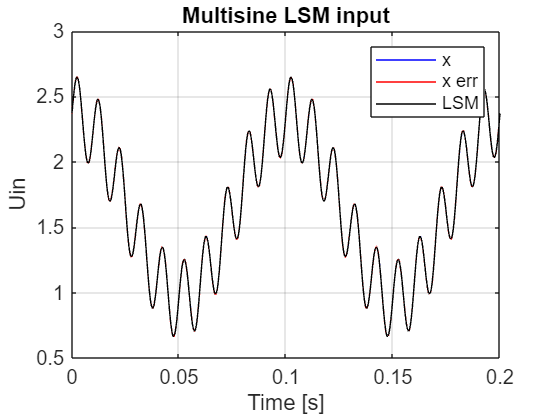


%plotting input
plot(t,x,'b')
hold on;
plot(t,x_err,'r-')
x_est = R1x_est*sin(2*pi*f1*t+fi1x_est)+R2x_est*sin(2*pi*f2*t+fi2x_est)+Kx(5);
plot(t,x_est,'k');
hold off;
grid on;
xlabel('Time [s]');
ylabel('Uin');
legend('x','x err','LSM')
title('Multisine LSM input')
xlim([0 2/f1])

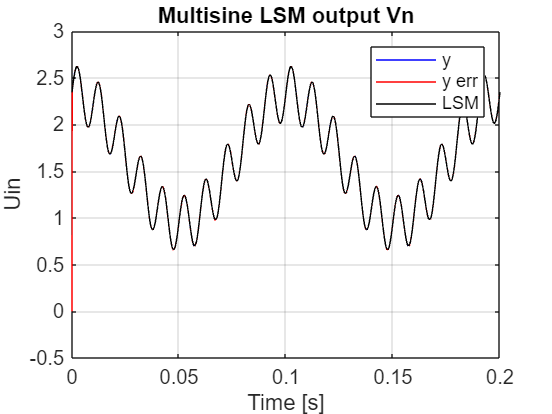


%plotting output Vn
plot(t,yN,'b')
hold on;
plot(t,yN_err,'r-')
yN_est = R1yN_est*sin(2*pi*f1*t+fi1yN_est)+R2yN_est*sin(2*pi*f2*t+fi2yN_est)+KyN(5);
plot(t,yN_est,'k');
hold off;
grid on;
xlabel('Time [s]');
ylabel('Uin');
legend('y','y err','LSM')
title('Multisine LSM output Vn')
xlim([0 2/f1])

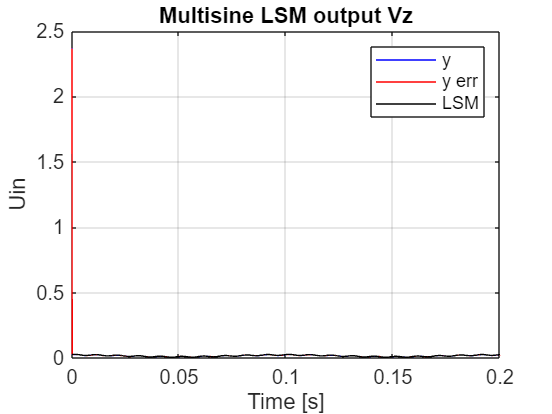


%plotting output Vz
plot(t,yZ,'b')
hold on;
plot(t,yZ_err,'r-')
yZ_est = R1yZ_est*sin(2*pi*f1*t+fi1yZ_est)+R2yZ_est*sin(2*pi*f2*t+fi2yZ_est)+KyZ(5);
plot(t,yZ_est,'k');
hold off;
grid on;
xlabel('Time [s]');
ylabel('Uin');
legend('y','y err','LSM')
title('Multisine LSM output Vz')
xlim([0 2/f1])

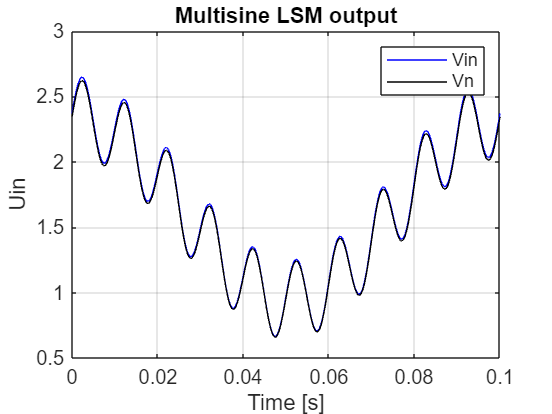


%plotting Vin and Vr together
plot(t,x_est,'b');
hold on;
plot(t,yN_est,'k');
hold off;
grid on;
xlabel('Time [s]');
ylabel('Uin');
legend('Vin','Vn')
title('Multisine LSM output')
xlim([0 1/f1])

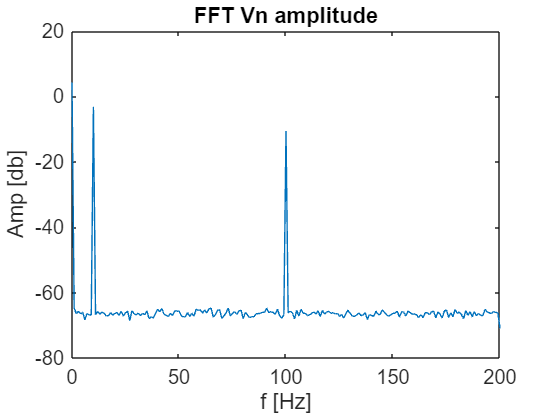

% Frequency domain, Calculating components with FFT
% Output Vn
f = [0:length(t)-1]*fs/length(t);
f_egy = f(1:end/2);
Yn_err = fft(yN_err);
Yn_err_egyodlalas = abs(Yn_err)/length(yN_err);
Yn_err_egyodlalas = [Yn_err_egyodlalas(1),2*Yn_err_egyodlalas(2:end/2)];
Yn_err_f = angle(Yn_err(1:end/2));

% Plotting
plot(f_egy,20*log10(Yn_err_egyodlalas))
xlabel('f [Hz]')
ylabel('Amp [db]')
title('FFT Vn amplitude')
xlim([0,2*f2])

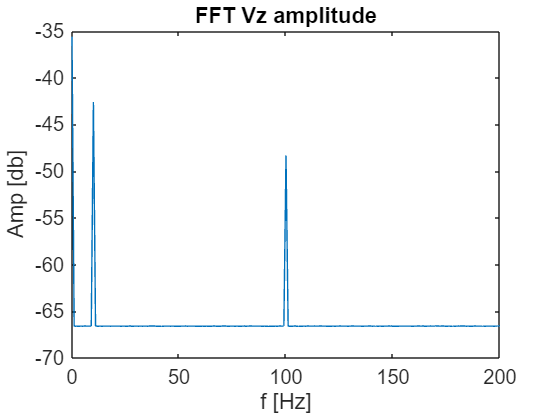

% plot(f_egy,Yn_err_f)
% xlabel('f [Hz]')
% ylabel('Phase [rad]')
% title('FFT Vn phase')


% Output Vz
Yz_err = fft(yZ_err);
Yz_err_egyodlalas = abs(Yz_err)/length(yZ_err);
Yz_err_egyodlalas = [Yz_err_egyodlalas(1),2*Yz_err_egyodlalas(2:end/2)];
Yz_err_f = angle(Yz_err(1:end/2));

% Plotting
plot(f_egy,20*log10(Yz_err_egyodlalas))
xlabel('f [Hz]')
ylabel('Amp [db]')
title('FFT Vz amplitude')
xlim([0,2*f2])

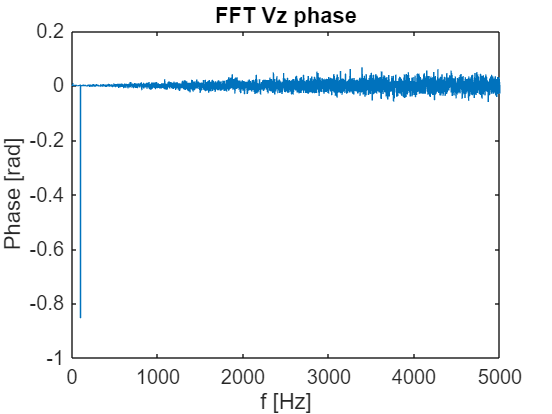

plot(f_egy,Yz_err_f)
xlabel('f [Hz]')
ylabel('Phase [rad]')
title('FFT Vz phase')

% Calculating impedance from FFT
R1yN_fft = Yn_err_egyodlalas(f_egy==f1);
R2yN_fft = Yn_err_egyodlalas(f_egy==f2);
R1yZ_fft = Yz_err_egyodlalas(f_egy==f1);
R2yZ_fft = Yz_err_egyodlalas(f_egy==f2);
f1yN_fft = Yn_err_f(f_egy==f1)+pi/2;
f2yN_fft = Yn_err_f(f_egy==f2)+pi/2;
f1yZ_fft = Yz_err_f(f_egy==f1)+pi/2;
f2yZ_fft = Yz_err_f(f_egy==f2)+pi/2;

% Theoretical value
G_f1 = abs(R+1j*2*pi*f1*L)

G_f1 = 10.0197

G_f2 = abs(R+1j*2*pi*f2*L)

G_f2 = 11.8101

Gf_f1 = angle(R+1j*2*pi*f1*L)

Gf_f1 = 0.0627

Gf_f2 = angle(R+1j*2*pi*f2*L)

Gf_f2 = 0.5610


R_f1 = G_f1*cos(Gf_f1)

R_f1 = 10.0000

R_f2 = G_f2*cos(Gf_f2)

R_f2 = 10

L_f1 = G_f1*sin(Gf_f1)/(2*pi*f1)

L_f1 = 0.0100

L_f2 = G_f2*sin(Gf_f2)/(2*pi*f2)

L_f2 = 0.0100


% Calculated from FFT
Za_fft_f1 = Rn*R1yZ_fft/R1yN_fft

Za_fft_f1 = 10.7041

Za_fft_f2 = Rn*R2yZ_fft/R2yN_fft

Za_fft_f2 = 12.9213

Zf_fft_f1 = f1yZ_fft-f1yN_fft

Zf_fft_f1 = 0.0622

Zf_fft_f2 = f2yZ_fft-f2yN_fft

Zf_fft_f2 = 0.6551


% Calculating impedance from LSM
Za_f1 = Rn*R1yZ_est/R1yN_est

Za_f1 = 10.7041

Za_f2 = Rn*R2yZ_est/R2yN_est

Za_f2 = 12.9213

Zf_f1 = fi1yZ_est-fi1yN_est

Zf_f1 = 0.0622

Zf_f2 = fi2yZ_est-fi2yN_est

Zf_f2 = 0.6551


% Calculated componenets from FFT
R_f1 = Za_fft_f1*cos(Zf_fft_f1)

R_f1 = 10.6834

R_f2 = Za_fft_f2*cos(Zf_fft_f2)

R_f2 = 10.2467

L_f1 = Za_fft_f1*sin(Zf_fft_f1)/(2*pi*f1)

L_f1 = 0.0106

L_f2 = Za_fft_f2*sin(Zf_fft_f2)/(2*pi*f2)

L_f2 = 0.0125


% Calculated componenets from LSM
R_f1 = Za_f1*cos(Zf_f1)

R_f1 = 10.6834

R_f2 = Za_f2*cos(Zf_f2)

R_f2 = 10.2467

L_f1 = Za_f1*sin(Zf_f1)/(2*pi*f1)

L_f1 = 0.0106

L_f2 = Za_f2*sin(Zf_f2)/(2*pi*f2)

L_f2 = 0.0125